MathTools HW2 Question 3

2024-10-3

## a)

(Part a is hand-written, please see attached notebook.)

clear all; clc; close all;

addpath('hw2-files/');
load('constrainedLS.mat'); 

## b)

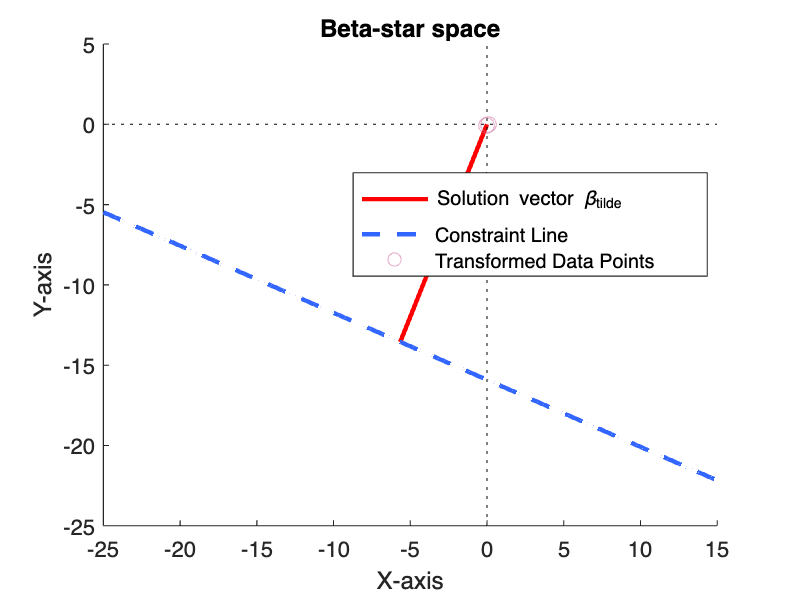

[u,s,v] = svd(data);
s_smallest = s(1:2, :);

%The shortest vector beta_tilde_opt should lies in the same direction as 
% w_tilde. 
w_tilde = s_smallest \ (v' * w); %transformed vector w_tilde
beta_tilde = (1/(w_tilde' * w_tilde))*w_tilde; % Shortest vector beta_tilde

figure; hold on;
plot([0, beta_tilde(1)], [0, beta_tilde(2)], 'r-', 'LineWidth', 2); %beta tilde
%quiver(0, 0, beta_tilde(1), beta_tilde(2), 0, 'r', 'LineWidth', 2, 'MaxHeadSize', 2);  % Vector arrow for beta_tilde

%Plotting the linear constrain
x_vals = linspace(-25, 15, 100); 
y_vals = (1 - x_vals * w_tilde(1)) / w_tilde(2);
plot(x_vals, y_vals, '--','color',[0.2, 0.4, 1.0], 'LineWidth', 2);

%Transformed data points
data_transformed = s_smallest \ (v' * data');
%transformed_data = s(1:2, 1:2) * v(:, 1:2)' * data';  %first two singular values
scatter(data_transformed(:,1), data_transformed(:,2), 50,[0.8,0.4,0.6], 'MarkerFaceColor', 'none', 'MarkerEdgeAlpha', 0.5); % Plot data points

%General settings for plotting
xlabel('X-axis');
ylabel('Y-axis');
title('Beta-star space');
legend('Solution vector \beta_{tilde}','Constraint Line', 'Transformed Data Points',Location='best');
xlim([-25 15]); 

%Using the 0-point oringins
plot([0, 0], ylim, 'k:', 'LineWidth', 0.5,'HandleVisibility', 'off');
plot(xlim, [0, 0], 'k:', 'LineWidth', 0.5,'HandleVisibility', 'off');

hold off; 

## c)

Please see attached note for part c, which will explain part of the logic.

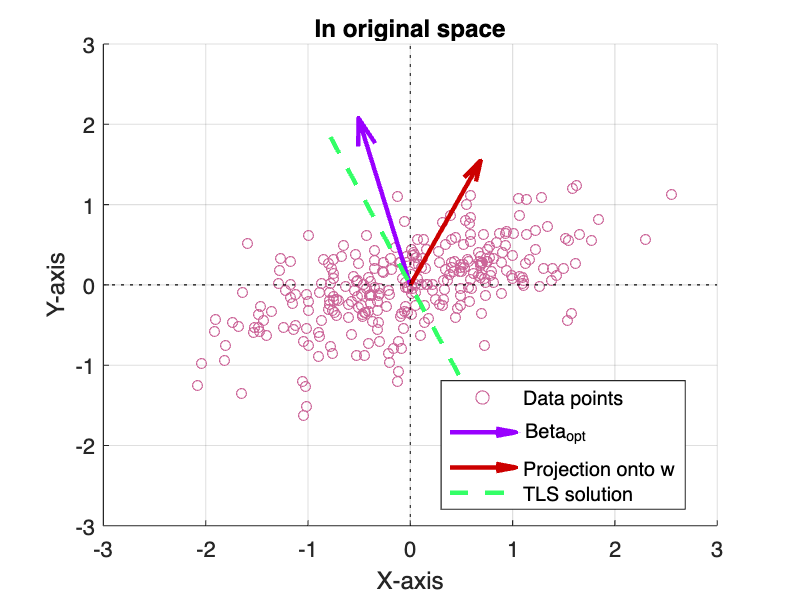

load('constrainedLS.mat'); 
[U, S, V] = svd(data); 

figure; hold on;

% Original data points
scatter(data(:, 1), data(:, 2), 20,[0.8,0.4,0.6], 'MarkerFaceColor', 'none');

% Transform beta_tilde back to the original space
beta_opt = V(:, 1:2) * (S(1:2, 1:2) \ beta_tilde);
quiver(0, 0, beta_opt(1), beta_opt(2), 0, 'Color', [0.6, 0.0, 1.0], 'LineWidth', 2, 'MaxHeadSize', 0.5);

%Dot product of beta_opt and w
dot_product = sum(beta_opt .* w);

%Squared norm of w
norm_squared_w = sum(w.^2);

%Projection of beta_opt onto w
beta_proj = (dot_product / norm_squared_w) * w;
quiver(0, 0, beta_proj(1), beta_proj(2), 0, 'Color', [0.8, 0.0, 0.0], 'LineWidth', 2, 'MaxHeadSize', 0.5);

% Total Least Squares (TLS) solution
beta_tls = V(:, 2);

%Two points of TLS: Extend the line in both directions by choosing another point along the line
t = linspace(-2, 2, 2);  
tls_line = t' * beta_tls';  

plot(tls_line(:, 1), tls_line(:, 2), '--', 'Color', [0.2, 1.0, 0.4], 'LineWidth', 2);

%General settings for plotting
legend('Data points', 'Beta_{opt}', 'Projection onto w', 'TLS solution', 'Location', 'best');
xlabel('X-axis');xlim([-3 3]); 
ylabel('Y-axis');ylim([-3 3]); 
title('In original space');
grid on;

%Using the 0-point oringins
plot([0, 0], ylim, 'k:', 'LineWidth', 0.5,'HandleVisibility', 'off');
plot(xlim, [0, 0], 'k:', 'LineWidth', 0.5,'HandleVisibility', 'off');

hold off;

From the graph, we can see that Beta_opt is not prependicular to w; and it's not the same as the total least squares solution. 